nf_data = [

2.56
2.67
2.78
2.91
3.03
3.12
3.23
3.32
3.37
3.41
-1.66
-1.69
-1.77
-1.86
-2.00
-2.15
-2.26
-2.39
-2.48
-2.53
-2.55
1.66
1.70
1.76
1.83
1.92
2.03
2.11
2.22
2.31
2.38
2.42
-1.66
-1.67
-1.72
-1.77
-1.86
-1.97
-2.06
-2.16
-2.25
-2.31
-2.37
-2.40
-2.41
1.66
1.68
1.73
1.80
1.87
1.96
2.06
2.13
2.20
2.26
2.28
-1.66
-1.67
-1.70
-1.76
-1.81
-1.89
-1.97
-2.04
-2.12
-2.20
-2.25
-2.29
-2.32
1.66
1.66
1.68
1.72
1.79
1.86
1.96
2.07
2.15
2.23
2.30
2.33
-1.66
-1.67
-1.71
-1.78
-1.84
-1.94
-2.05
-2.13
-2.23
-2.32
-2.37
1.66
1.67
1.70
1.75
1.80
1.87
1.95
2.02
2.11
2.19
2.25
2.30
2.33
-1.66
-1.69
-1.75
-1.81
-1.90
-1.97
-2.07
-2.16
-2.22
-2.30
-2.35
-2.38
1.66
1.67
1.69
1.75
1.80
1.89
1.99
2.07
2.16
2.25
2.30
2.34
2.36
-1.66
-1.69
-1.75
-1.80
-1.89
-1.97
-2.07
-2.16
-2.23
-2.31
-2.36
-2.39
1.66
1.66
1.68
1.73
1.77
1.85
1.93
2.01
    ];

%t = linspace(0, 3000, 150);
t = t(1:150)';

figure
clf
hold on
plot(t, nf_data, 'b')

ylabel("Angle (rads)")
xlabel("Time (ms)")
title("Measured Motor Speed Vs. Time")

% finding w_n

[peaks, is] = findpeaks(nf_data);

peaks = peaks(2:end)

peaks =     2.4200
    2.2800
    2.3300
    2.3300
    2.3600


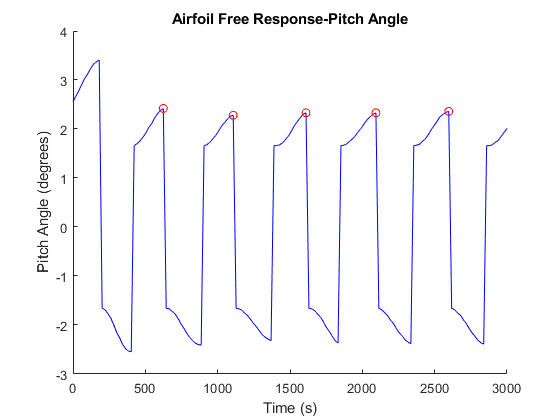

is = is(2:end);

time_peaks = [];
for i = 1:length(is)
    time_peaks(end+1) = t(is(i));
end

plot(time_peaks, peaks, "ro")

xlabel("Time (s)")
ylabel("Pitch Angle (degrees)")
title("Airfoil Free Response-Pitch Angle")


time_diff = diff(time_peaks);
T = mean(time_diff);
w_n = 1/T

w_n = 0.0020